# **Weather Project**

This is a project applying machine learning method to predict whether in Helsinki, Finland. The dataset is a set of measurements such as temperature, atmospheric pressure, collected by the weather station 2978 in Helsinki from January 2010 to December 2018. The data have adapted from a public dataset avaliable at Aalto University. The original data has been resampled by day and simplified as following: 			

– “T" is the air temperature (in degrees Celsius)

– “Po" is the atmospheric pressure at weather station level (in millimeters of mercury)

– “P" is the atmospheric pressure reduced to mean sea level (in millimeters of mercury. 		

– “Ff" is the mean wind speed (in meters per second).

– “Tn" is the minimum air temperature over the past day (in degrees Celsius,). – “Tx" is the maximum air temperature, over the past day (in degrees Celsius) – “W" is the horizontal visibility, in km.

– “Td" is the dewpoint temperature (in degrees Celsius).

– “U" is the relative humidity (in percentage) 		

For the all the attributes (excluding the OBSERVED variable), the mean and the variance values for each day are provided. For example, “T mu" indicates the mean of the air temperature, and “T var" indicates the variance of the air temperature, which constitutes for 17 independent variables and 2 target variables. 

✓  the first attribute “datetime", is an index indicating the date in the format YYYY-MM-DD. 						

✓  all the other attributes are continuous 						

✓  the 18th attribute (target attribute) – variable OBSERVED – is a binary variable, where 0 (not dry) indicates that the amount of precipitation was more than 0.3 millimeters, and 1 (dry) indicates that the amount of precipitation was less than 0.3 millimeters. 						

✓  the 19th attribute (target attribute) is the relative mean humidity (variable U_mu) and represents a target continuous variable 						

This project will execute the whole process of data mining and build models for prediction in Matlab programming language. The first model is based on regression method to predict the relative mean of humidity based on set of predictors matrix. The second model applied classification and ROC curve method to anticipate whether the weather is dry or not on a specific day. 

## Data exploration and preparation

**Input data **

rng('default');
T=readtable('weatherHelsinki.xlsx')

T = 3202×19 table
     datetime       T_mu      Po_mu      P_mu     Ff_mu     Tn_mu     Tx_mu      W_mu      Td_mu      T_var     Po_var      P_var     Ff_var     Tn_var    Tx_var    W_var     Td_var     OBSERVED     U_mu 
    ___________    _______    ______    ______    ______    ______    ______    ______    _______    _______    _______    _______    _______    ______    ______    ______    

Summarise the table 

summary(T)

Variables:

    datetime: 3202×1 datetime

        Values:

            Min       01-Jan-2010 00:00:00
            Median    21-Jul-2014 12:00:00
            Max       31-Dec-2018 00:00:00

    T_mu: 3202×1 double

        Values:

            Min       -22.675 
            Median        6.4 
            Max        26.146 

    Po_mu: 3202×1 double

        Values:

            Min         729.5 
            Median     759.21 
            Max        790.42 

    P_mu: 3202×1 double

        Values:

            Min        729.85 
            Median     759.54 
            Max        790.81 

    Ff_mu: 3202×1 double

        Values:

            Min        1.1667 
            Median      3.375 
            Max        10.792 

    Tn_mu: 3202×1 double

        Values:

            Min        -26.2  
            Median       4.7  
            Max        23.65  

    Tx_mu

**Data Visualization**

Visualise relationship between attributes to better understand data. 

First the relationship between the air temperature (T) and atmospheric pressure (P) with the OBSERVED variable is checked in the following graph. . 

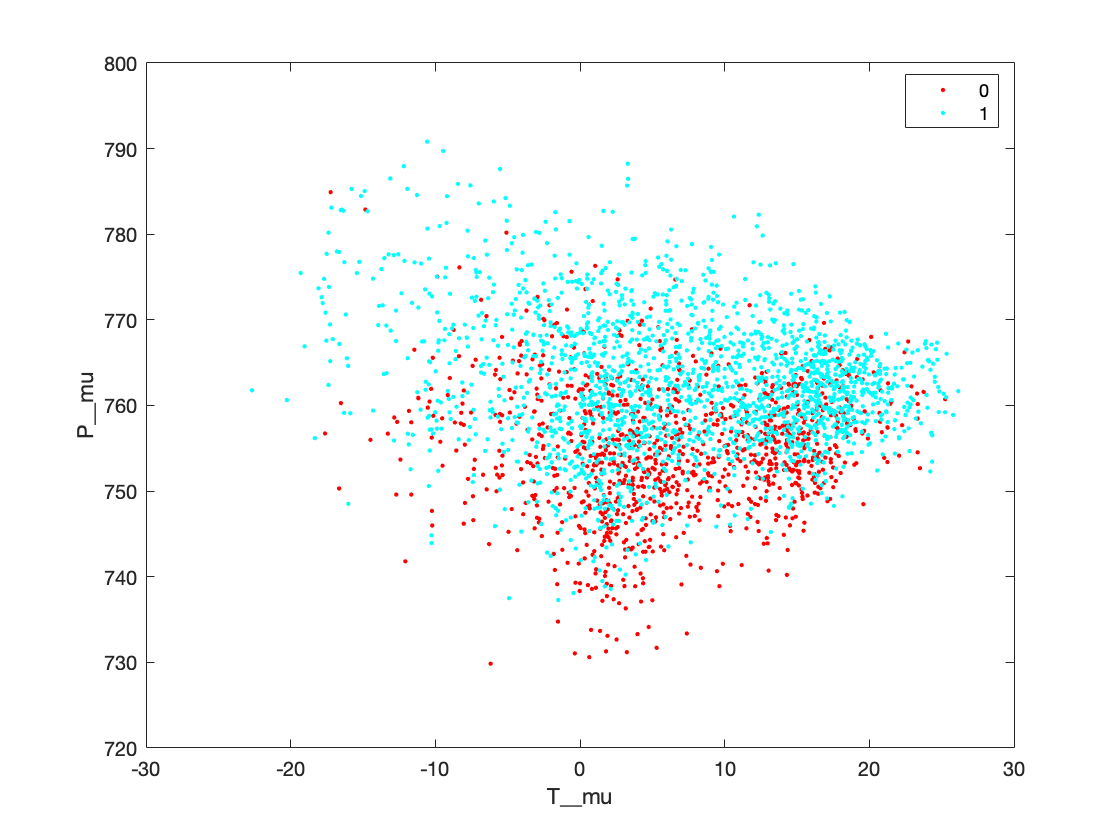

gscatter(T.T_mu,T.P_mu,T.OBSERVED)
xlabel('T__mu');
ylabel('P__mu');

The 2D draft shows that days with high pressure and low temperature is usually dry. In contrast, high temperature and low pressure tend to have not dry whather. 

Check the minimum air temperature over the past day (in degree Celsius)

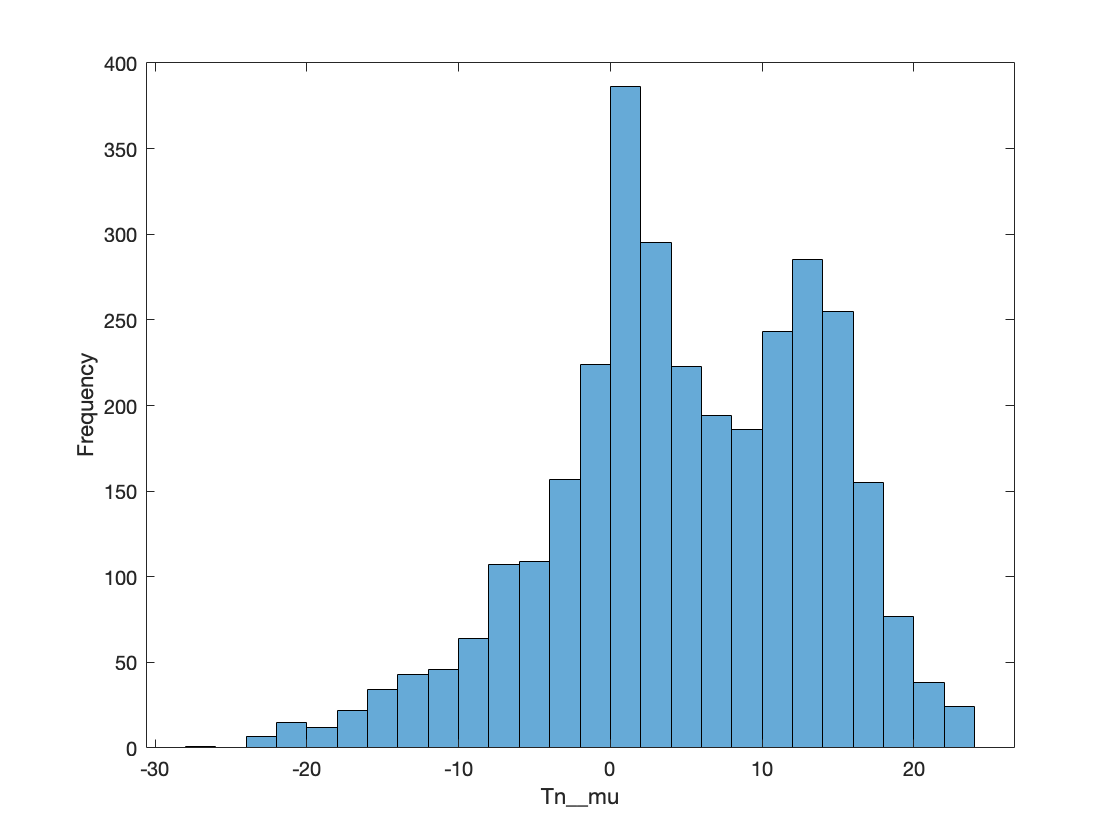

histogram(T.Tn_mu)
xlabel('Tn__mu')
ylabel('Frequency')

The distribution is right-skewed. The most frequent minimum temperature is around 0 degree Celsius. 

The dataset is split into 2 groups: dry and not dry. 

[grpObs,ObsVals] = findgroups(T.OBSERVED);
maxTd_mu = splitapply(@max,T.Td_mu,grpObs)

maxTd_mu =    20.3000
   21.4625


The average maximum dew point temperature of "not dry" group (0) is 20.3 degrees Celsius and 21.46 degrees for "dry" group (1). 

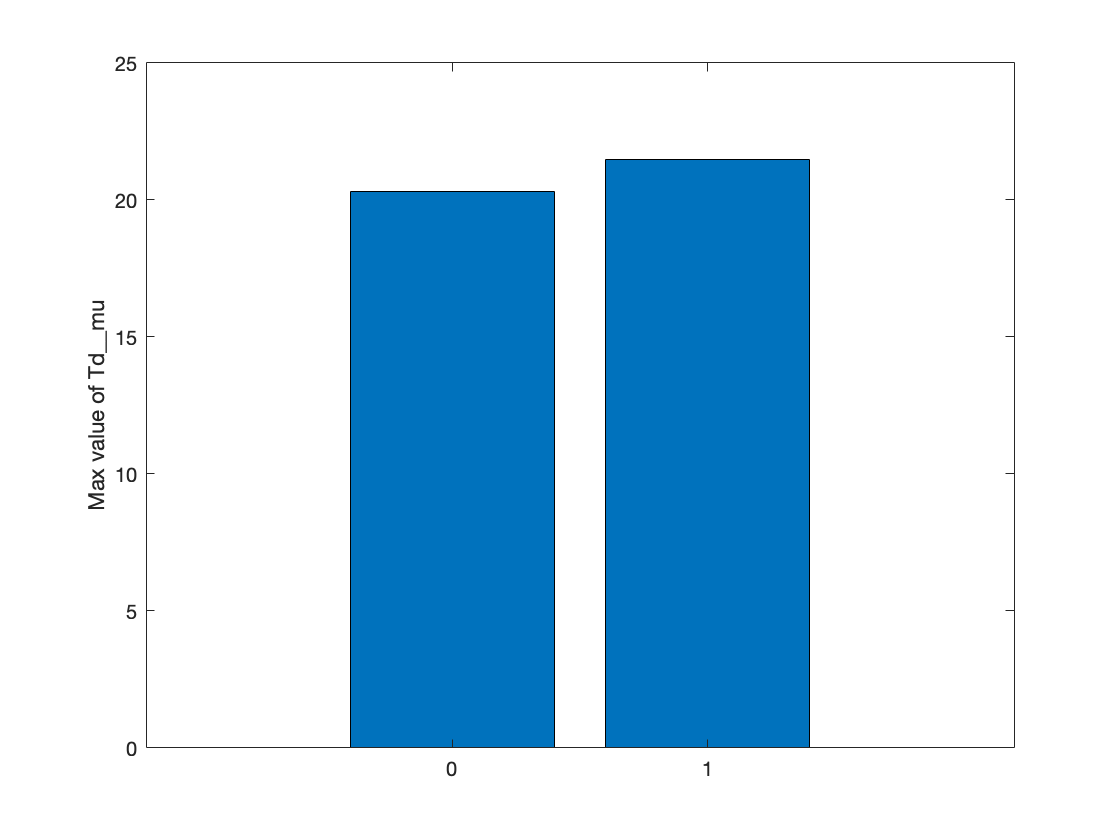

bar(maxTd_mu)
xticklabels(ObsVals)
ylabel("Max value of Td__mu")

The same process is applied to atmospheric pressure: 

meanP_var = splitapply(@mean,T.P_var,grpObs)

meanP_var =     5.4376
    3.0735


Mean atmospheric pressure of group 0 (not dry) is much higher than group 1 (dry). 

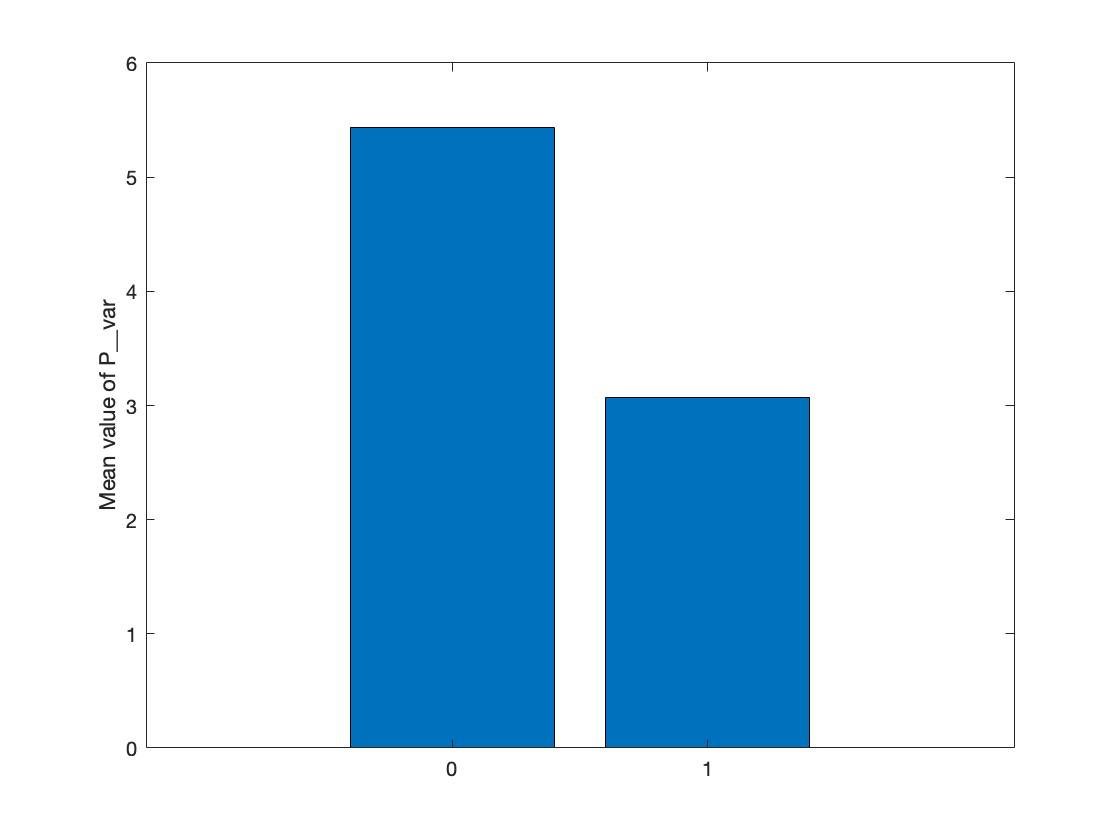

bar(meanP_var)
xticklabels(ObsVals)
ylabel("Mean value of P__var")

Separate datetime to year, month and day variables. 

[T.YY,T.MM,T.DD] = ymd(T.datetime);
T.datetime = [];

 The dataset is split into independent variables and dependent variables for the next part of model building. Y1 variable is the target vavriable for binary logistic regression and Y2 variable is for multivariate linear regression. The other 17 variables formed a matrix X as indepedent variables. 

Y1 = T.OBSERVED;
Y2 = T.U_mu;

X = table2array(T);
X(:,17:18)=[];

# Principal Component Analysis (PCA) and clustering

### PCA Analysis: 

Pairwise correlation of all variables: 

C = corr(X)

C =     1.0000   -0.0752   -0.0765   -0.1474    0.9927    0.9945    0.1805    0.9565    0.1386   -0.1909   -0.1910   -0.0246    0.2275    0.0590   -0.0692   -0.1699    0.0414    0.3040    0.0044
   -0.0752    1.0000    1.0000   -0.3173   -0.1021   -0.0575    0.0656   -0.1513    0.2141   -0.2343   -0.2338   -0.2305    0.1203    0.1362   -0.2006    0.0108    0.0227   -0.0526    0.0247
   -0.0765    1.0000    1.0000   -0.3171   -0.1035   -0.0588    0.0653   -0.1526    0.2140   -0.2338   -0.2335   -0.2303    0.1199    0.1363   -0.2005    0.0112    0.0226   -0.0531    0.0248
   -0.1474   -0.3173   -0.3171    1.0000   -0.1227   -0.1670    0.0895   -0.1635   -0.2422    0.3516    0.3512    0.4005   -0.1705   -0.1119    0.0859    0.0971   -0.0136    0.1051    0.0029
    0.9927   -0.1021   -0.1035   -0.1227    1.0000    0.9815    0.1517    0.9627    0.0495   -0.1835   -0.1836   -0.0312    0.1808   -0.0044   -0.0672   -0.2196    0.0508    0.3184    0.0039
    0.9945   -0.0575   -0.0588   -0.1670 

Based on the table above, we can see that some variables highly correlated to others such as T, Tn, Tx variables have the correlation of 0.99. Therefore, we have to implement PCA: 

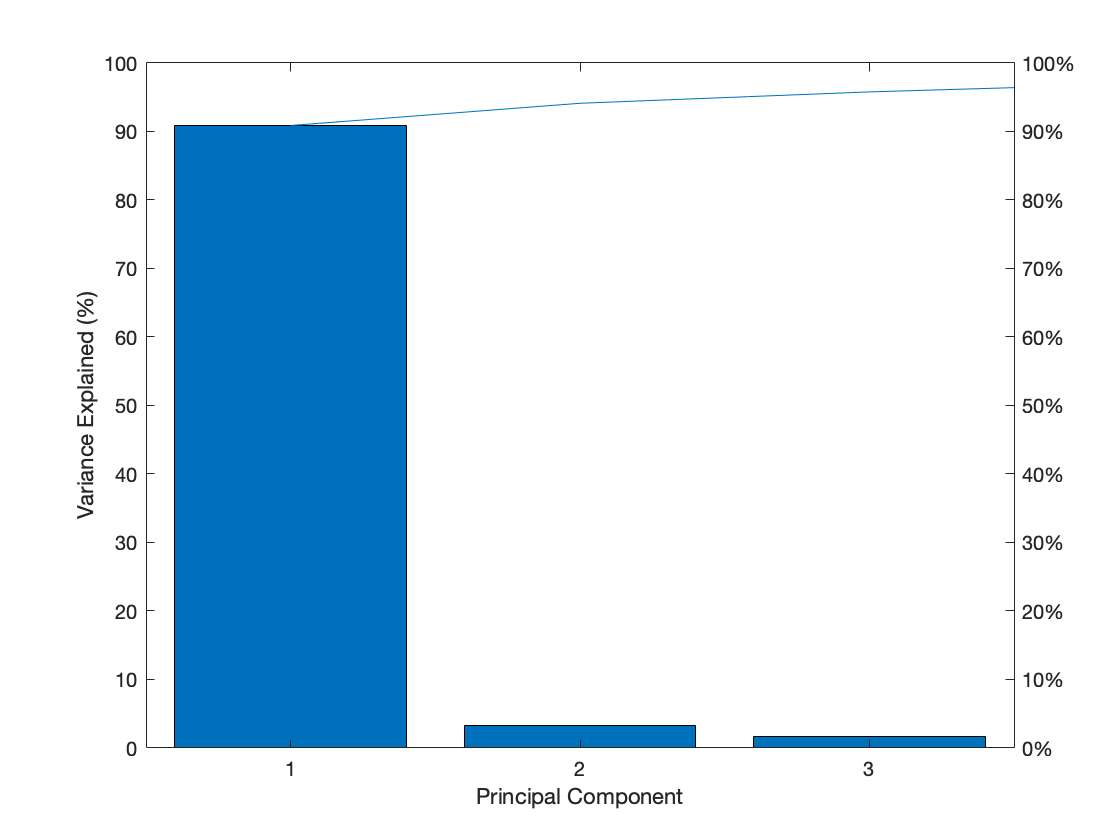

[coeff,score,latent,~,explained]= pca(X);
figure
    pareto(explained)
    xlabel('Principal Component')
    ylabel('Variance Explained (%)')

Based on the PCA analysis, the first 2 principal components explained more than 94% of variance. So we choose them to perform the PCA analysis. 

### K-means Clustering: 

Testing with different clusters: 

T1 = score(:,1:2);

#### 2 clusters: 

[cidx2,cmeans2] = kmeans(T1,2,'replicates',10,'display','final');

Replicate 1, 6 iterations, total sum of distances = 8.90381e+06.
Replicate 2, 7 iterations, total sum of distances = 8.90382e+06.
Replicate 3, 7 iterations, total sum of distances = 8.90382e+06.
Replicate 4, 8 iterations, total sum of distances = 8.90381e+06.
Replicate 5, 8 iterations, total sum of distances = 8.90381e+06.
Replicate 6, 6 iterations, total sum of distances = 8.90382e+06.
Replicate 7, 6 iterations, total sum of distances = 8.90381e+06.
Replicate 8, 7 iterations, total sum of distances = 8.90381e+06.
Replicate 9, 7 iterations, total sum of distances = 8.90381e+06.
Replicate 10, 4 iterations, total sum of distances = 8.90382e+06.
Best total sum of distances = 8.90381e+06


ptsymb = {'bs','r^','md','go','c+'};
for i = 1:2
    clust = find(cidx2==i);
    plot(T1(clust,1),T1(clust,2),ptsymb{i});
    hold on
end
plot(cmeans2(:,1),cmeans2(:,2),'ko');
plot(cmeans2(:,1),cmeans2(:,2),'kx');
hold off
xlabel('First pc');
ylabel('Second pc');
grid on

#### 3 clusters: 

[cidx3,cmeans3] = kmeans(T1,3,'replicates',10,'display','final');

Replicate 1, 14 iterations, total sum of distances = 4.98909e+06.
Replicate 2, 27 iterations, total sum of distances = 4.98902e+06.
Replicate 3, 25 iterations, total sum of distances = 4.98902e+06.
Replicate 4, 18 iterations, total sum of distances = 4.98909e+06.
Replicate 5, 20 iterations, total sum of distances = 4.98909e+06.
Replicate 6, 7 iterations, total sum of distances = 4.98902e+06.
Replicate 7, 12 iterations, total sum of distances = 4.98902e+06.
Replicate 8, 30 iterations, total sum of distances = 4.98902e+06.
Replicate 9, 27 iterations, total sum of distances = 4.98902e+06.
Replicate 10, 33 iterations, total sum of distances = 4.98902e+06.
Best total sum of distances = 4.98902e+06



ptsymb = {'bs','r^','md','go','c+'};
for i = 1:3
    clust = find(cidx3==i);
    plot(T1(clust,1),T1(clust,2),ptsymb{i});
    hold on
end
plot(cmeans3(:,1),cmeans3(:,2),'ko');
plot(cmeans3(:,1),cmeans3(:,2),'kx');
hold off
xlabel('First pc');
ylabel('Second pc');
grid on

#### 4 clusters: 

[cidx4,cmeans4] = kmeans(T1,4,'replicates',10,'display','final');

Replicate 1, 7 iterations, total sum of distances = 3.26765e+06.
Replicate 2, 31 iterations, total sum of distances = 3.26768e+06.
Replicate 3, 6 iterations, total sum of distances = 3.26768e+06.
Replicate 4, 13 iterations, total sum of distances = 3.26768e+06.
Replicate 5, 27 iterations, total sum of distances = 3.26947e+06.
Replicate 6, 15 iterations, total sum of distances = 3.26947e+06.
Replicate 7, 20 iterations, total sum of distances = 3.26768e+06.
Replicate 8, 14 iterations, total sum of distances = 3.26947e+06.
Replicate 9, 37 iterations, total sum of distances = 3.26768e+06.
Replicate 10, 16 iterations, total sum of distances = 3.26768e+06.
Best total sum of distances = 3.26765e+06


ptsymb = {'bs','r^','md','go','c+'};
for i = 1:4
    clust = find(cidx4==i);
    plot(T1(clust,1),T1(clust,2),ptsymb{i});
    hold on
end
plot(cmeans4(:,1),cmeans4(:,2),'ko');
plot(cmeans4(:,1),cmeans4(:,2),'kx');
hold off
xlabel('First pc');
ylabel('Second pc');
grid on

#### 5 clusters: 

[cidx5,cmeans5] = kmeans(T1,5,'replicates',10,'display','final');

Replicate 1, 34 iterations, total sum of distances = 2.53701e+06.
Replicate 2, 35 iterations, total sum of distances = 2.53701e+06.
Replicate 3, 18 iterations, total sum of distances = 2.53701e+06.
Replicate 4, 40 iterations, total sum of distances = 2.53701e+06.
Replicate 5, 14 iterations, total sum of distances = 2.52679e+06.
Replicate 6, 14 iterations, total sum of distances = 2.53701e+06.
Replicate 7, 35 iterations, total sum of distances = 2.79688e+06.
Replicate 8, 33 iterations, total sum of distances = 2.53701e+06.
Replicate 9, 18 iterations, total sum of distances = 2.52635e+06.
Replicate 10, 15 iterations, total sum of distances = 2.79608e+06.
Best total sum of distances = 2.52635e+06



ptsymb = {'bs','r^','md','go','c+'};
for i = 1:5
    clust = find(cidx5==i);
    plot(T1(clust,1),T1(clust,2),ptsymb{i});
    hold on
end
plot(cmeans5(:,1),cmeans5(:,2),'ko');
plot(cmeans5(:,1),cmeans5(:,2),'kx');
hold off
xlabel('First pc');
ylabel('Second pc');
grid on

Choose the optimal number of clusters: 

E = evalclusters(T1,'kmeans','silhouette','klist',[2:5])

E =   SilhouetteEvaluation with properties:

    NumObservations: 3202
         InspectedK: [2 3 4 5]
    CriterionValues: [0.8583 0.7905 0.7154 0.6600]
           OptimalK: 2


kbest = E.OptimalK

kbest = 2

figure
plot(E)

The plot shows that the highest silhouette value occurs at two clusters, suggesting that the optimal number of clusters is 2.

We can create a scatter plot (2D)  to visually examine the suggested clusters.

figure;
gscatter(T1(:,1),T1(:,2),E.OptimalY,'rbg','xod')
xlabel('first pc');
ylabel('second pc');
grid on

### Hierarchical Clustering: 

At linkage 0.6, there is 4 clusters. 

hidx = cluster(clustTreeCos,'Maxclust',4);
hidxbis=clusterdata(T1,'maxclust',4','linkage', 'average');
cutoff = 0.6;
dendrogram(clustTreeCos,'ColorThreshold',cutoff)

Evaluate this clustering: 

We use the silhoutte coefficient to evaluate the quality of this cluster solution.

[silh4tree,h] = silhouette(T1,hidx);

mean(silh4tree)					

ans = 0.3292

The mean Silhouette value is 0.3292. The mean and the graph tell us that this is not the optimal clustering. 

### GMM Clustering: 

Predictors of the dataset are reduced and transformed (according to the principal components in the previous part). GMM (Gaussian Mixture Model) clustering is adopted with 3 clusters and 1000 maximum iterations (for the Expectation-Maximization algorithm). 

k = 3; % Number of GMM components
options = statset('MaxIter',1000);
gm = fitgmdist(T1,k,'Options',options);
P = posterior(gm,T1)

P =     0.0000    0.9998    0.0002
    0.3661    0.0177    0.6162
    0.0000    1.0000    0.0000
         0    1.0000    0.0000
    0.0000    0.0731    0.9269
    0.0000    0.8673    0.1327
    0.0000    0.0413    0.9587
    0.5945    0.0120    0.3936
    0.8153    0.0068    0.1779
    0.7939    0.0082    0.1979


P(8,:)

ans =     0.5945    0.0120    0.3936


As we can see, the probability of the 8th observation in 1st cluster is 0.5952 in 2nd cluster is 0.3928 and 3rd is 0.012. Hence, it is the most optimal compared to others. 

# Multivariate Regression Model		

The goal of this task is to predict the relative mean humidity (variable Y2, i.e. variable U_mu), based on predictors matrix X. 

The dataset is randomly divided into train and test data, considering 70% of the data for the training data and 30% for the test data (non-stratified partition). Specifically, divide your predictors matrix (X) in Xtrain and Xtest. Similarly, divide your target variable of interest Y2 in Y2train and Y2test.  	

rng('default');
cv = cvpartition(height(T),'holdout',0.30);
Xtrain = X(training(cv),:);
Y1train = Y1(training(cv),:);
Y2train = Y2(training(cv),:);

Xtest = X(test(cv),:);
Y1test = Y1(test(cv),:);
Y2test = Y2(test(cv),:);

A linear regression model is trained using all the available predictors in X (use training data) 	

mdl=fitlm(Xtrain,Y2train,'linear')

mdl = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15 + x16 + x17 + x18 + x19

Estimated Coefficients:
                    Estimate         SE          tStat        pValue  
                   __________    __________    _________    __________

    (Intercept)        132.55        24.943       5.3141    1.1787e-07
    x1                -4.3021      0.068169      -63.109             0
    x2                 1.5314          1.35       1.1344       0.25676
    x3                -1.5706        1.3494      -1.1639       0.24457
    x4               -0.27974      0.032686      -8.5584    2.0994e-17
    x5                0.27852      0.043519       6.3998    1.8912e-10
    x6        

Some variables has p-value that is not significant at 5% level. Those will be removed and then, we build a second model. 

Xtrain1 = Xtrain;
Xtrain1(:,[2,3,10,11,12,17,18,19]) = [];
mdl1=fitlm(Xtrain1,Y2train,'linear')

mdl1 = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11

Estimated Coefficients:
                   Estimate         SE         tStat       pValue  
                   _________    __________    _______    __________

    (Intercept)       98.184       0.14556     674.53             0
    x1               -4.4138      0.068039    -64.871             0
    x2              -0.17182      0.028614    -6.0046    2.2327e-09
    x3               0.31934       0.04395     7.2659    5.0982e-13
    x4              -0.31318      0.041788    -7.4945    9.5432e-14
    x5             -0.064486     0.0035349    -18.243     2.061e-69
    x6                4.5276      0.018496     244.79             0
    

Xtest1 = Xtest;
Xtest1(:,[2,3,10,11,12,17,18,19]) = [];

Applying the model on the test data, we predict the target variable. 

Y2predicted_test= mdl.predict(Xtest)

Y2predicted_test =    89.6914
   87.5950
   84.5713
   90.8698
   91.3966
   92.1759
   95.8211
   87.3122
   86.6713
   85.8967


Y2predicted_test1= mdl1.predict(Xtest1)

Y2predicted_test1 =    89.5111
   87.2742
   84.8841
   91.2562
   91.8013
   92.5289
   96.2429
   88.2260
   87.4211
   86.7890


MSEtest = immse(Y2test,Y2predicted_test)

MSEtest = 1.9483

MSEtest2 = immse(Y2test,Y2predicted_test1)

MSEtest2 = 1.9677

Compare MSE of 2 models, we see that there is not much difference between them. 

## Principal component regression (PCR):  

 Apply Principal Component Analysis over training predictors and train 3 linear regression models (use training data): 		

Xtrain; Y2train;
Xtest; Y2test; 

[coeff,scoreTrain,~,~,explained,mu] = pca(Xtrain);

#### PCR with 2 PCs: 

scoreTrain2comp = scoreTrain(:,1:2);
mdl2 = fitlm(scoreTrain2comp,Y2train);
scoreTest2comp = (Xtest-mu)*coeff(:,1:2);
YTest_predicted2 = predict(mdl2,scoreTest2comp);

Let's graph the predicted value and the real value to compare

figure
plot(Y2test,YTest_predicted2,".")
hold on
plot(Y2test,Y2test,'Linewidth',2)
hold off
legend('Predicted Response','Actual response','location','bestoutside')

#### PCR with 3 PCs: 

scoreTrain3comp = scoreTrain(:,1:3);
mdl3 = fitlm(scoreTrain3comp,Y2train);
scoreTest3comp = (Xtest-mu)*coeff(:,1:3);
YTest_predicted3 = predict(mdl3,scoreTest3comp);     

Let's graph the predicted value and the real value to compare

figure
plot(Y2test,YTest_predicted3,".")
hold on
plot(Y2test,Y2test,'Linewidth',2)
hold off
legend('Predicted Response','Actual response','location','bestoutside')

#### PCR with 4 PCs: 

scoreTrain4comp = scoreTrain(:,1:4);
mdl4 = fitlm(scoreTrain4comp,Y2train);
scoreTest4comp = (Xtest-mu)*coeff(:,1:4);
YTest_predicted4 = predict(mdl4,scoreTest4comp);  

Let's graph the predicted value and the real value to compare

figure
plot(Y2test,YTest_predicted4,".")
hold on
plot(Y2test,Y2test,'Linewidth',2)
hold off
legend('Predicted Response','Actual response','location','bestoutside')

Evaluate which models predict most correctly. 

MSEpcr2comp = immse(Y2test,YTest_predicted2)

MSEpcr2comp = 123.9894

MSEpcr3comp = immse(Y2test,YTest_predicted3)

MSEpcr3comp = 96.5464

MSEpcr4comp = immse(Y2test,YTest_predicted4)

MSEpcr4comp = 63.5570

The objective is to minimise MSE and the model with first 4pcs seems smallest among 3. Therefore, it is the most fitted model. We can see that through the figures which illustrate each model above. 

# Classification and ROC Curve:

The goal of this is to classify the weather conditions either as 1(dry) or 0 (not dry) (variable Y1, i.e. variable OBSERVED), based on predictors matrix X. We apply the same holdout non-stratified partition (split intro training and test data) as in regression model. Reuse Xtrain and Xtest and split the variable of interest Y1 into Y1train and Y1test. 						

Y1train; Y1test; 
Y1test = logical(Y1test);

We train a logistic regression model using all the available predictors in X (use training data) 						

glm = fitglm(Xtrain, Y1train,'Distribution','binomial','link','logit')

glm = Generalized linear regression model:
    logit(y) ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15 + x16 + x17 + x18 + x19
    Distribution = Binomial

Estimated Coefficients:
                    Estimate         SE         tStat        pValue  
                   __________    __________    ________    __________

    (Intercept)       -240.44        48.163     -4.9923    5.9676e-07
    x1                0.24141       0.13173      1.8326      0.066858
    x2                -4.2362        2.5263     -1.6769      0.093565
    x3                 4.3313        2.5253      1.7151      0.086322
    x4               -0.25491       0.06256     -4.0747     4.607e-05
    x5                0.36909      0.086367      4.27

Y1_glm = predict(glm, Xtest);
[xxtest,yytest,Tresholds,auctest] = perfcurve(Y1test,Y1_glm,'true');

Now, we apply Principal Component Analysis over training predictors and train a classification tree using the first 3 principal components (use training data) 

[coeff,scoreTrain,~,~,explained,mu] = pca(Xtrain);        
scoreTrain3comp = scoreTrain(:,1:3); 
[coeff,scoreTest,~,~,explained,mu] = pca(Xtest);        
scoreTest3comp = scoreTest(:,1:3); 
t = fitctree(scoreTrain3comp,Y1train);
Y1_t = predict(t, scoreTest3comp); 
[xxtest1,yytest1,Tresholds1,auctest1] = perfcurve(Y1test,Y1_t,'true');

figure
plot(xxtest,yytest)
hold on 
plot(xxtest1,yytest1)
xlabel('False positive rate'); ylabel('True positive rate');
legend('Logistic Regression','Classification tree'); 
title('ROC Curve with test data applied by logistic regression and classification tree'); 
hold off 

The graph below clearly shows that AUC of logistic regression model is larger than AUC of tree model. Thus, Logistic regression model predicts better than the other. 

[auctest auctest1]				

ans =     0.8799    0.6865


# Classification and Confusion Matrix				

The goal of this is to classify again the weather conditions either as 1(dry) or 0 (not dry) (variable Y1, i.e. variable OBSERVED), based on predictors matrix X. However, now, we use Support Vector Machine (SVM) classifier with K-fold partition (k=3). 	 

rng(1); 
cvp = cvpartition(Y1,'KFold',3);

SVM classifier (3-fold cross validation) is built. 

mdlSVM = fitcsvm(X,Y1,'Standardize',true,'CVPartition', cvp, 'KernelFunction','RBF','KernelScale','auto');
cross_validation_missclassificatio_rate_svm= kfoldLoss(mdlSVM)

cross_validation_missclassificatio_rate_svm = 0.2027

cross_validation_Accuracy_svm=1-cross_validation_missclassificatio_rate_svm

cross_validation_Accuracy_svm = 0.7973

Next, classification tree is trained based on matrix X.

t= fitctree(X,Y1,'CVPartition', cvp);
cross_validation_missclassificatio_rate_t= kfoldLoss(t)

cross_validation_missclassificatio_rate_t = 0.2764

cross_validation_Accuracy_t=1-cross_validation_missclassificatio_rate_t

cross_validation_Accuracy_t = 0.7236

### Confusion matrix:  

% Confusion matrix of SVM classifier
predicted_classes_svm = kfoldPredict(mdlSVM);
C = confusionchart(Y1,predicted_classes_svm,'RowSummary','row-normalized');
title('Confusion matrix of SVM model');

% Confusion matrix of classification tree
predicted_classes_t = kfoldPredict(t);
C = confusionchart(Y1,predicted_classes_t,'RowSummary','row-normalized');
title('Confusion matrix of Classification tree model');

A = [cross_validation_Accuracy_svm cross_validation_Accuracy_t]

A =     0.7973    0.7236


The accuracy of svm model is 0.7973 while the accuracy of tree model is 0.7264.

TPR of svm model is 85.5% while of the tree model is 77.9%.

TNR of svm model is 73% while of the tree model is 62%. 

So the svm model predicts better than the other.

# Conclusion 

In conclusion, the goal of this project is to build different models for prediction of weather and choose the most fitted one. This report has covered data mining process, carried out principal component analysis. It also built various regression model to predict the mean humidity in Helsinki. They are multivariate regression, stepwise regression and PCR with 2, 3 and 4 PCs. The best model is the adjusted linear regression. 

To anticipate whether the weather is dry or not, different models were trained and built binary logistic regression, classification tree and support vector machine classifier. Binary logistic regression and support vector machine are better model than classification tree. Either one of them can be chosen. 